close all;
clear;
clc;
load data/threeTankParameter1.mat
load data/testData1.mat
addpath(genpath('lib'),genpath('gpml-matlab-master'));

xD = [testData.x1,testData.x2,testData.x3];
dxD = [testData.dx1,testData.dx2,testData.dx3];
yD = [testData.y1,testData.y2,testData.y3];
n = 3;
m = 3;

%%own hyper variation 
hyperparameter.sigmaN = 0.56;
hyperparameter.sigmaF = 0.86;
hyperparameter.l = 0.43;

%%GPML
hyperparameter.sigmaN = 0.5096; 
hyperparameter.sigmaF = 0.9494;
hyperparameter.l  = 0.3483;

%%GPML
hyperparameter.sigmaN = 0.5; 
hyperparameter.sigmaF = 0.9;
hyperparameter.l  = 0.35;


sigmaX = [1e-7, 0, 0; 0, 1e-7, 0; 0, 0, 1e-7];
sigmaY = [1e-5, 0, 0; 0, 1e-5, 0; 0, 0, 1e-5];
kernel = {@squaredExponentialKernel, @squaredExponentialKernel, @squaredExponentialKernel};
meanFct = {@meanDx1,@meanDx2,@meanDx3};

hyperparameter.B = [ 0.0001 , 0 ; 0 , 0.0001];
hyperparameter1 = hyperparameter;
hyperparameter2 = hyperparameter;
hyperparameter3 =  hyperparameter;
hyperparameter1.beta = [1.012800000000000e-04; 2.441000000000000e-05];
hyperparameter2.beta = [2.428000000000000e-05; 3.743000000000000e-05];
hyperparameter3.beta = [2.441000000000000e-05; 2.428000000000000e-05];

% hyperparameter1.beta = [0; 0];
% hyperparameter2.beta = [0; 0];
% hyperparameter3.beta = [0; 0];

hyperparameterCell = {hyperparameter1, hyperparameter2, hyperparameter3};


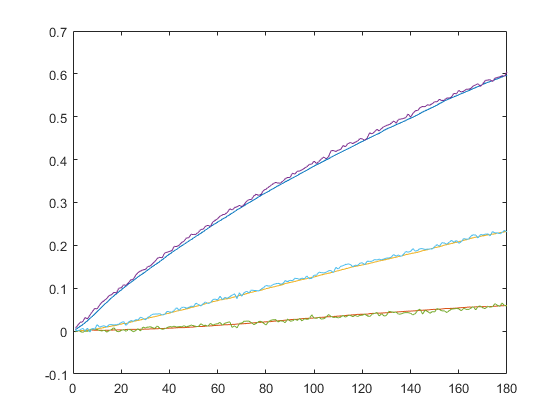

threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);

gP = DynamicSystemGP(xD,dxD,yD,hyperparameterCell,kernel,meanFct,sigmaX,sigmaY);
pf = ParticleFilter(gP,5);
xGP = [0,0,0];
xGpEst = zeros(180,3);
dxGpEst = zeros(180,3);
sigma = zeros(180,3);
yGpEst = zeros(180,3);
x = zeros(180,3);
time = zeros(180,1);
xK = [0,0,0];

for i = 1 : 180
    %waterTank
    time(i) = i;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    %GP System
    tic
    xGpEst(i,:) = pf.prediction(yK,1);
    calcTime(i) = toc;
    
    [xGP,dxGpEst(i,:),sigma(i,:)] = gP.stateTransition(xGP,1);
    
    
    %xGpEst(i,:) = xGP;
    %yGpEst(i,:) = gP.measurement(xGP);
end
plot(xGpEst);
hold on;
plot(x)
%plot(yGpEst)
hold off;

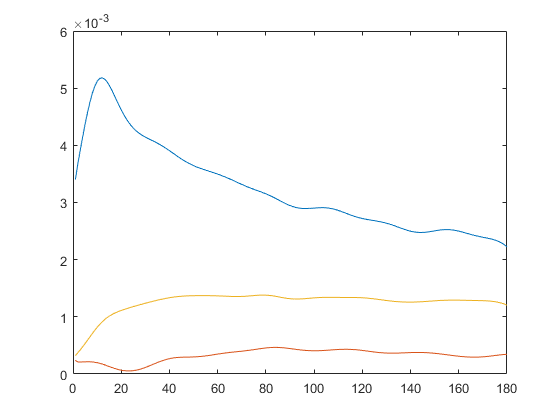

plot(dxGpEst)

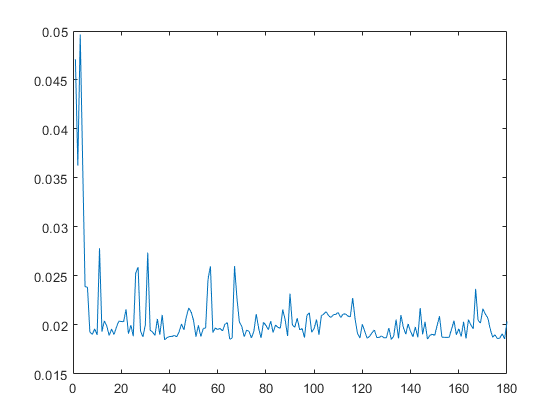


plot(calcTime)

calcTimeM = mean(calcTime);


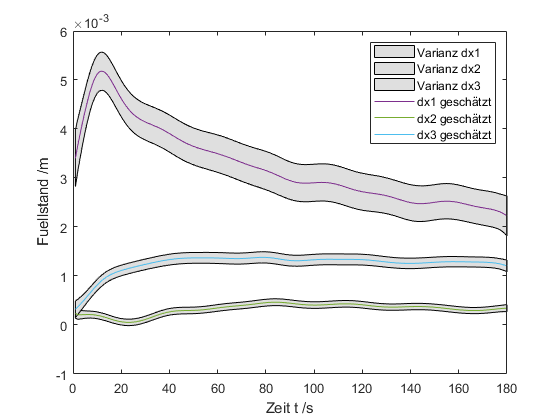

f1 = [dxGpEst(:,1)+2*sqrt(sigma(:,1)); flip(dxGpEst(:,1)-2*sqrt(sigma(:,1)),1)];
f2 = [dxGpEst(:,2)+2*sqrt(sigma(:,2)); flip(dxGpEst(:,2)-2*sqrt(sigma(:,2)),1)];
f3 = [dxGpEst(:,3)+2*sqrt(sigma(:,3)); flip(dxGpEst(:,3)-2*sqrt(sigma(:,3)),1)];


fill([time; flip(time,1)], f1, [7 7 7]/8)
hold on;
fill([time; flip(time,1)], f2, [7 7 7]/8)
fill([time; flip(time,1)], f3, [7 7 7]/8)
plot(time, dxGpEst(:,1));
plot(time, dxGpEst(:,2));
plot(time, dxGpEst(:,3));


legend('Varianz dx1','Varianz dx2','Varianz dx3', 'dx1 geschätzt', 'dx2 geschätzt', 'dx3 geschätzt');
xlabel('Zeit t /s')
ylabel('Fuellstand /m')
hold off;